# input data

file='C:\Users\PhotonUser\My Files\Temporary Files\Lab4-5Bode.txt';
fileID=fopen(file);
textstuff=textscan(fileID, '%s %s %s','Delimiter',' ');
fclose(fileID);

## input CircuitLab data

clabfile='C:\Users\PhotonUser\My Files\Temporary Files\CircuitLab_simulation_2022-02-20T20_37_59.718Z.csv';
clabdata=readmatrix(clabfile);

clabfreq=clabdata(:,1);
clabfreq=2.*pi.*clabfreq;
clabgain=clabdata(:,2);
clabphase=clabdata(:,3);

## organize and separate frequency data

freq=textstuff{1,1};
freq=string(freq);
freq=freq(4:64);
freq=str2double(freq);
freq=freq.*2.*pi;

## organize and separate gain data

gain=textstuff{1,2};
gain=string(gain);
gain=gain(4:64);
gain=str2double(gain);

## organize and separate phase shift data

phase=textstuff{1,3};
phase=string(phase);
phase=phase(4:64);
phase=str2double(phase);

## measured values

f=[103.82,311.46,1038.2,3114.6,10382];
f=2.*pi.*f;
g=[1.003,1.05,1.558,0.145,0.27];
g=20*log10(g);
p=[8.37,17.94,-106.519,-162.58,-168.188];

## theoretical data

wn=10000;
zet=0.2446;
w=logspace(3,6,200);

sn=1j*w./wn;
H=1./(sn.^2+zet*sn+1);
MagH=abs(H);
PhaseHRad=angle(H);

## gain plot

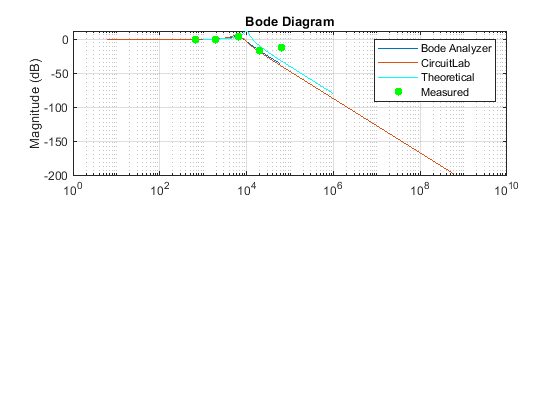

subplot(2,1,1);
semilogx(freq,(gain),'DisplayName','Bode Analyzer')
hold on
plot(clabfreq,clabgain,'DisplayName','CircuitLab')
hold on
semilogx(w,20*log10(MagH),'c','DisplayName','Theoretical')
hold on
scatter(f(1),g(1),'filled','g','DisplayName','Measured')
hold on
scatter(f(2),g(2),'filled','g')
hold on
scatter(f(3),g(3),'filled','g')
hold on
scatter(f(4),g(4),'filled','g')
hold on
scatter(f(5),g(5),'filled','g')
hold on
grid on
ylabel('Magnitude (dB)')
title('Bode Diagram')
legend('Bode Analyzer','CircuitLab','Theoretical','Measured')
hold off

## phase shift plot

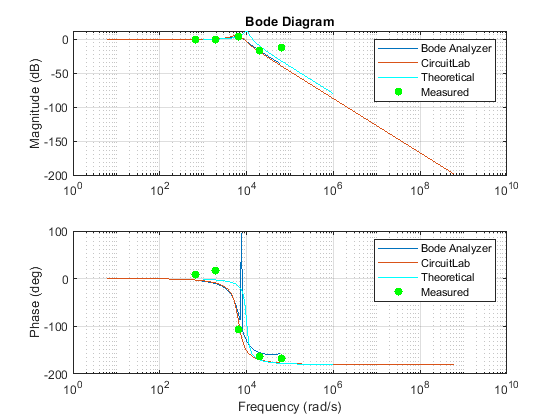

subplot(2,1,2)
semilogx(freq,phase,'DisplayName','Bode Analyzer')
hold on
plot(clabfreq,clabphase,'DisplayName','CircuitLab')
hold on 
semilogx(w,PhaseHRad*(180/pi),'c','DisplayName','Theoretical')
hold on 
scatter(f(1),p(1),'filled','g','DisplayName','Measured')
hold on
scatter(f(2),p(2),'filled','g')
hold on
scatter(f(3),p(3),'filled','g')
hold on
scatter(f(4),p(4),'filled','g')
hold on
scatter(f(5),p(5),'filled','g')
hold on
grid on 
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Bode Analyzer','CircuitLab','Theoretical','Measured')